# CHW2 - 99102061 RohamKaveie

## Problem 1 : Amplitude modulation

**Part 0 : generate m(t)**

% Parameters
fs = 10000;             % Sampling frequency (Hz)
dt = 1/fs;              % Time step
t = -10:dt:15;          % Time vector (covers both terms)
u = @(x) double(x >= 0);% Unit step function

% Message signal definition
m = exp(-6*t) .* (u(t-4) - u(t-8)) + exp(6*t) .* (u(-t-8) - u(-t-4));

**Part 1: Plot in Time & Frequency, find Bandwidth**

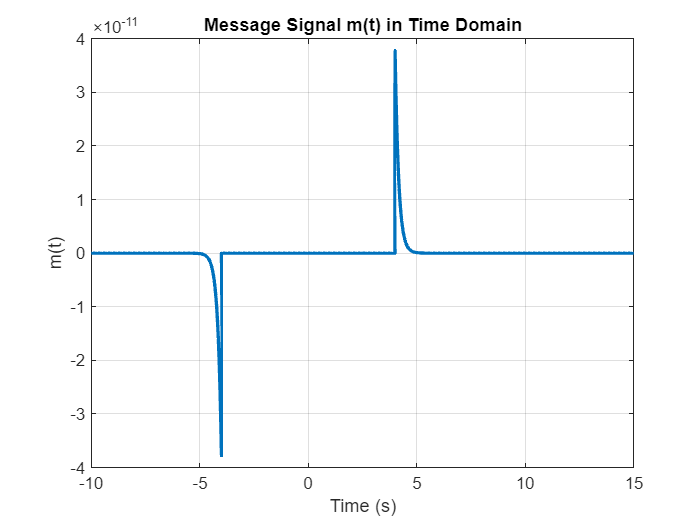

% Plot in time domain
figure;
plot(t, m, 'LineWidth', 2);
xlabel('Time (s)'); ylabel('m(t)');
title('Message Signal m(t) in Time Domain');
grid on;

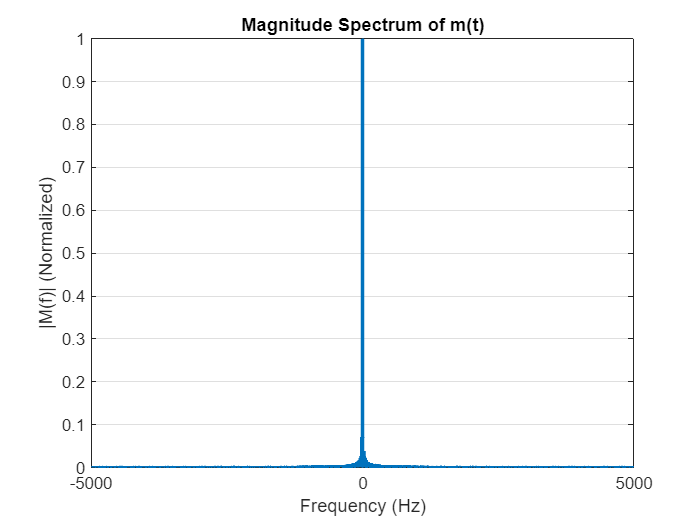


% Frequency domain (FFT)
N = length(m);
f = (-N/2:N/2-1)*(fs/N); % Frequency vector
M_f = fftshift(fft(m, N));

figure;
plot(f, abs(M_f)/max(abs(M_f)), 'LineWidth', 2);
xlabel('Frequency (Hz)'); ylabel('|M(f)| (Normalized)');
title('Magnitude Spectrum of m(t)');
grid on;


% Find bandwidth: where |M(f)| > 1% of max
thresh = 0.01 * max(abs(M_f));
indices = find(abs(M_f) > thresh);
BW = (f(indices(end)) - f(indices(1))); % Bandwidth in Hz

disp(['Estimated Bandwidth: ', num2str(BW), ' Hz']);

Estimated Bandwidth: 219.9991 Hz


*TODO explain how the bandwitdh are calculated*

 **Part 2: AM Modulation and Spectrum **

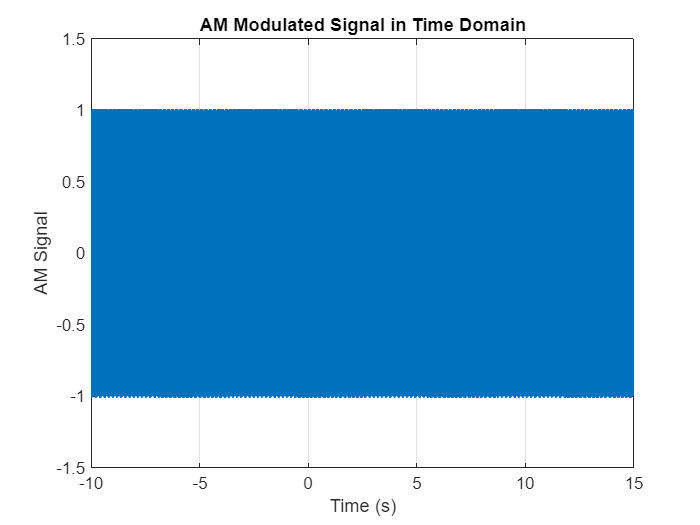

% AM Modulation Parameters
fc = 500;            % Carrier frequency (Hz)
Ac = 1;              % Carrier amplitude
ka = 0.8;            % Modulation index (choose < 1 for no overmodulation)

% AM signal
s_am = (Ac + ka*m) .* cos(2*pi*fc*t);

% Time domain plot
figure;
plot(t, s_am, 'LineWidth', 2);
xlabel('Time (s)'); ylabel('AM Signal');
title('AM Modulated Signal in Time Domain');
grid on;

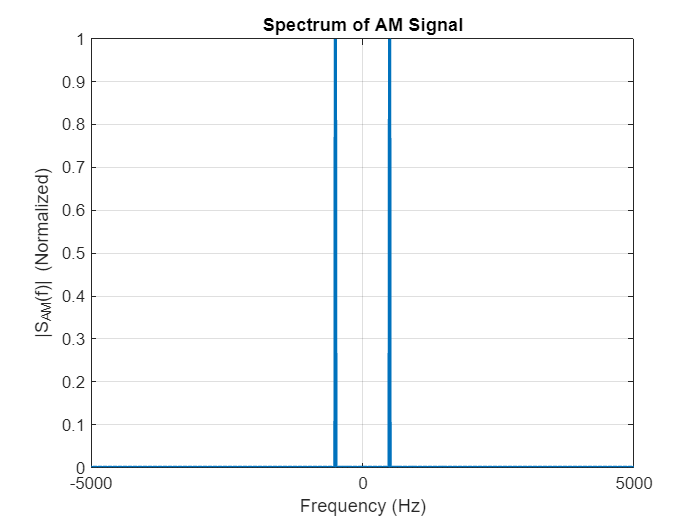


% Frequency domain plot
S_AM_f = fftshift(fft(s_am, N));
figure;
plot(f, abs(S_AM_f)/max(abs(S_AM_f)), 'LineWidth', 2);
xlabel('Frequency (Hz)'); ylabel('|S_{AM}(f)| (Normalized)');
title('Spectrum of AM Signal');
grid on;

**Part 3: Envelope Detector (RC Circuit) Simulation**

function y = envelope_detector(x, fs, RC, y0)
    % x: input signal
    % fs: sampling frequency
    % RC: time constant (R*C)
    % y0: initial output value
    y = zeros(size(x));
    y(1) = y0;
    alpha = RC/(RC-1);
    for n = 2:length(x)
        if abs(x(n)) > y(n-1)
            y(n) = abs(x(n));
        else
            y(n) = alpha*(y(n-1));
        end
    end
end

Uasge:

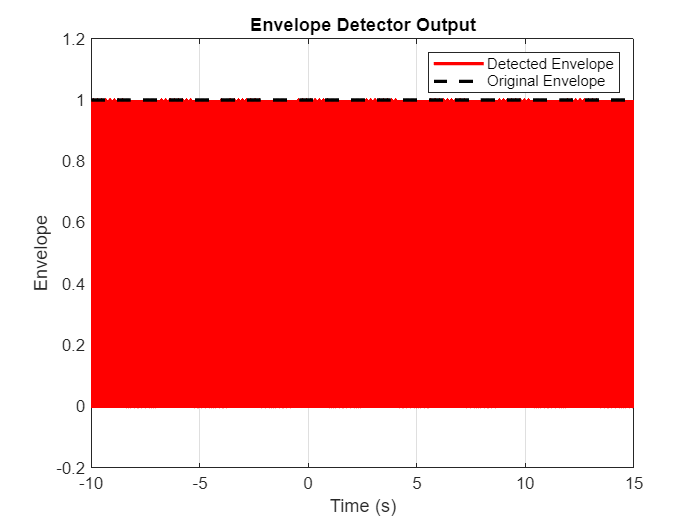

RC = 0.001; % Try different RC: too small = ripples, too large = slow response
y0 = 0;
env = envelope_detector(s_am, fs, RC, y0);

figure;
plot(t, env, 'r', t, Ac + ka*m, 'k--', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Envelope');
legend('Detected Envelope', 'Original Envelope');
title('Envelope Detector Output');
grid on;

**Part 4:Two-Stage Envelope Detection (Rectification + LPF)**

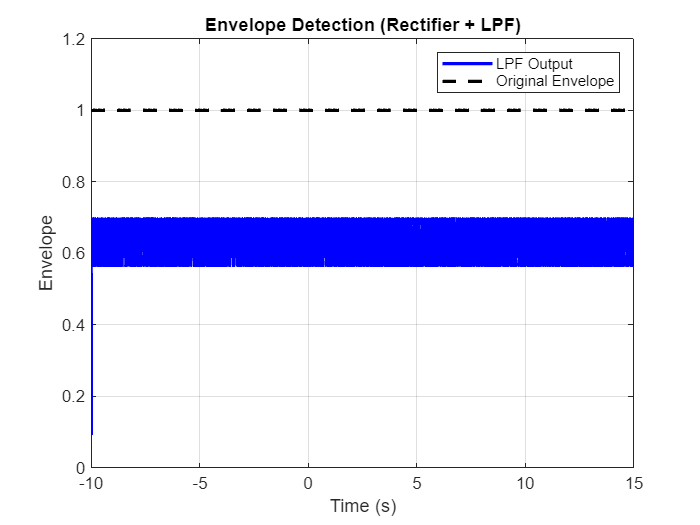

% 1. Rectify (absolute value)
rectified = abs(s_am);

% 2. Low-pass filter (simulate RC)
RC = 0.001; % Adjust as needed
alpha = dt/(RC+dt);
lpf_out = filter(alpha, [1 alpha-1], rectified, 0);

figure;
plot(t, lpf_out, 'b', t, Ac + ka*m, 'k--', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Envelope');
legend('LPF Output', 'Original Envelope');
title('Envelope Detection (Rectifier + LPF)');
grid on;

**Part 5: Coherent Demodulation**

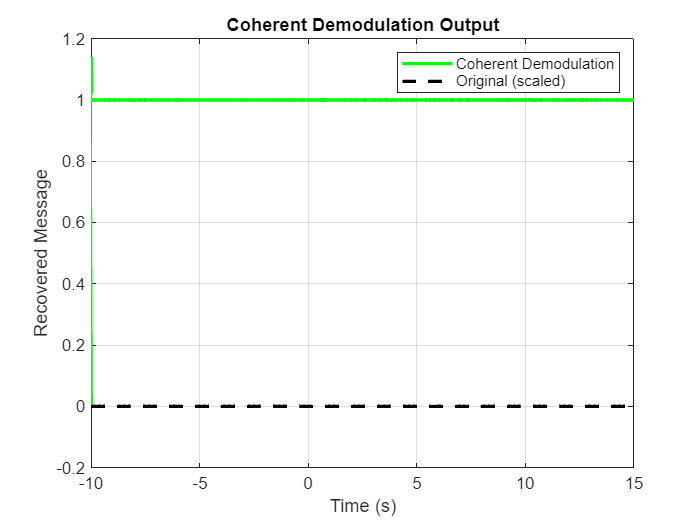

% Multiply by synchronized carrier
coherent = 2 * s_am .* cos(2*pi*fc*t);

% Low-pass filter to extract message
[b, a] = butter(6, (BW*2)/fs); % BW from part 1
coherent_demod = filter(b, a, coherent);

figure;
plot(t, coherent_demod, 'g', t, ka*m, 'k--', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Recovered Message');
legend('Coherent Demodulation', 'Original (scaled)');
title('Coherent Demodulation Output');
grid on;

**Part 6: Use MATLAB's **`amdemod`** and Compare**

% MATLAB built-in AM demodulation
demod_am = amdemod(s_am, fc, fs, 0, 0, 'coherent');

Error using amdemod (line 70)
Numerator and Denominator must be a pair.


figure;
plot(t, demod_am, 'm', t, m, 'k--', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Recovered Message');
legend('amdemod Output', 'Original');
title('AM Demodulation using amdemod');
grid on;

% Compare all methods
figure;
plot(t, m, 'k', t, env-Ac, 'r', t, lpf_out-Ac, 'b', t, coherent_demod/ka, 'g', t, demod_am, 'm', 'LineWidth', 1.5);
legend('Original', 'Envelope Detector', 'Rect+LPF', 'Coherent', 'amdemod');
xlabel('Time (s)'); ylabel('Message');
title('Comparison of Demodulation Methods');
grid on;

## Problem 2 : Frequency Modulation (FM) System

**Part 1: Generate FM signal**

% Parameters
fs = 10000; dt = 1/fs;
t = 0:dt:1; % 1 second duration
fc = 500;   % Carrier frequency in Hz
kf = 100;   % Frequency deviation constant (rad/s per unit message amplitude)

% Message signal (simple sinusoid for FM clarity)
fm = 5; % message frequency 5 Hz
m = cos(2*pi*fm*t);

% Integrate message for FM
m_int = cumsum(m)*dt; % Integral of message

% FM signal
s_fm = cos(2*pi*fc*t + 2*pi*kf*m_int);

% Plot time domain
figure;
plot(t, s_fm);
xlabel('Time (s)');
ylabel('s_{FM}(t)');
title('Frequency Modulated Signal in Time Domain');
grid on;

**Part 2: Plot frequency spectrum of FM signal**

N = length(s_fm);
f = (-N/2:N/2-1)*(fs/N);

S_fm = fftshift(fft(s_fm, N));

figure;
plot(f, abs(S_fm)/max(abs(S_fm)));
xlabel('Frequency (Hz)');
ylabel('Magnitude (Normalized)');
title('Spectrum of FM Signal');
grid on;
xlim([fc-500 fc+500]); % Zoom near carrier

**Part 3: Calculate and plot instantaneous frequency**

## 
$$f_{i\left(t\right)} =f_c +\frac{1}{2\pi \;}\frac{d}{\mathrm{dt}}\left(2\pi k_{f\;} \int \;m\left(t\right)\mathrm{dt}\right)=f_c +k_{f\;} m\left(t\right)$$


% Instantaneous phase
inst_phase = unwrap(angle(hilbert(s_fm)));

% Instantaneous frequency (derivative of phase)
inst_freq = [0 diff(inst_phase)/(2*pi*dt)];

figure;
plot(t, inst_freq);
hold on;
plot(t, fc + kf*m, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Instantaneous Frequency of FM Signal');
legend('Estimated from signal', 'Theoretical');
grid on;

**Part 4: FM Demodulation using differentiation and envelope detection**

% Differentiate FM signal
diff_s = [0 diff(s_fm)] * fs; % derivative approximation

% Envelope detection (rectification + LPF)
rectified = abs(diff_s);

% Low-pass filter design (cutoff ~ message frequency)
fc_lpf = 20; % cutoff frequency in Hz
[b,a] = butter(6, fc_lpf/(fs/2)); 
demodulated = filter(b,a,rectified);

% Normalize demodulated signal
demodulated = demodulated - mean(demodulated);
demodulated = demodulated / max(abs(demodulated));

% Plot demodulated message vs original
figure;
plot(t, m, 'k', t, demodulated, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('FM Demodulated Signal vs Original Message');
legend('Original Message', 'Demodulated Signal');
grid on;

**Part 5: Compare original and demodulated signals quantitatively**

% Compute correlation coefficient
corr_coef = corrcoef(m, demodulated);
disp(['Correlation coefficient between original and demodulated message: ', num2str(corr_coef(1,2))]);

% Plot error
error_signal = m - demodulated;
figure;
plot(t, error_signal);
xlabel('Time (s)');
ylabel('Error');
title('Error between Original and Demodulated Signal');
grid on;

## Problem 3: Pulse Amplitude Modulation (PAM) System

**Part 1: Generate the baseband message signal **$m\left(t\right)$

% Sampling parameters
fs = 1000;          % Sampling frequency in Hz
dt = 1/fs;          % Time step
t = -1:dt:5;        % Time vector covering before and after pulse

% Define message signal m(t)
m = double((t >= 0) & (t <= 2));  % Rectangular pulse from 0 to 2 seconds

% Plot message signal
figure;
plot(t, m, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('m(t)');
title('Message Signal m(t) - Rectangular Pulse');
grid on;

**Part 2: Generate PAM signal using a periodic impulse train**

% PAM parameters
T = 0.5;                    % Pulse repetition interval (seconds)
fs_pulse = 1/T;             % Pulse repetition frequency (Hz)

% Generate impulse train (Dirac comb approximation)
impulse_train = zeros(size(t));
impulse_indices = find(mod(t, T) < dt); % Indices where impulses occur
impulse_train(impulse_indices) = 1;

% Generate PAM signal
pam = m .* impulse_train;

% Plot PAM signal
figure;
stem(t, pam, 'filled');
xlabel('Time (s)');
ylabel('PAM Signal');
title('Pulse Amplitude Modulated (PAM) Signal');
grid on;

**Part 3: Plot the spectrum of the PAM signal**

% FFT parameters
N = length(pam);
f = (-N/2:N/2-1)*(fs/N);    % Frequency vector

% Compute FFT and shift zero frequency to center
PAM_f = fftshift(fft(pam, N));

% Plot magnitude spectrum (normalized)
figure;
plot(f, abs(PAM_f)/max(abs(PAM_f)), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('Normalized Magnitude');
title('Spectrum of PAM Signal');
grid on;
xlim([-10 10]); % Zoom near baseband and repetition frequency

**Part 4: Design and apply a low-pass filter to recover **$\mathit{\mathbf{m}}\left(\mathit{\mathbf{t}}\right)$

% Design low-pass Butterworth filter
fc = 1;                    % Cutoff frequency (Hz), less than fs_pulse/2 = 1 Hz
[b, a] = butter(6, fc/(fs/2));  % 6th order Butterworth filter

% Filter PAM signal to recover message
m_recovered = filter(b, a, pam);

% Plot recovered message signal
figure;
plot(t, m_recovered, 'LineWidth', 2);
hold on;
plot(t, m, 'k--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Recovered Message Signal after Low-Pass Filtering');
legend('Recovered m(t)', 'Original m(t)');
grid on;